R = fi(8, 0, 8, 0)

R =      8

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 8
        FractionLength: 0

G = fi(235, 0, 8, 0)

G =    235

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 8
        FractionLength: 0

B = fi(25, 0, 8, 0)

B =     25

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 8
        FractionLength: 0

hand = imread("lapa2.jpg")

hand = 158×198×3 uint8 array
hand(:,:,1) =

   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   188   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   190   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   191   191   191   191   191   191   191   191   191   192   192   194   194   194   193   193   194   195   195   192   191   191   191   193   192   196   195   194   197   198   191   186   183   183   182   185   188   189   188   189   187   186   187   188   189   188   187   188   188   188   188   188   188   188   188   187   187   187   187   187   187   187   186   187   187   186   187   187   187   187   186   187   187   186   186   185   185   185   185   185   184   184   184   184   184   184  

hand = imresize(hand, [128, 72])

hand = 128×72×3 uint8 array
hand(:,:,1) =

   186   186   186   186   186   186   186   186   186   186   186   187   188   188   188   188   188   188   188   188   189   189   189   189   189   188   188   189   189   189   191   192   192   191   189   191   195   191   181   183   187   185   186   186   186   186   186   185   185   185   184   185   184   184   183   182   182   182   182   181   180   181   180   179   180   179   177   176   175   174   170   169
   173   173   173   172   172   172   173   173   173   172   172   173   175   175   175   174   174   175   175   175   175   175   175   175   175   175   175   176   177   176   178   179   179   179   179   182   191   183   170   170   175   173   172   171   171   171   171   172   171   170   169   170   169   169   168   167   167   167   167   166   165   166   165   164   164   163   162   161   160   158   154   153
   173   173   173   174   174   174   174   174   174   173   173   174   176   176   176 

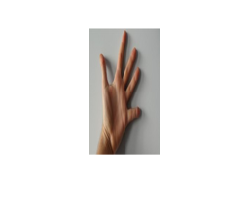

imshow(hand)

R = hand(:,:,1);
G = hand(:,:,2);
B = hand(:,:,3);

[Y, Cb, Cr] = RGB_to_YCbCr(R, G, B);

hand2 = cat(3, uint8(Y), uint8(Cb), uint8(Cr));

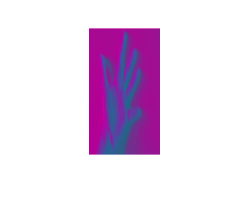

imshow(hand2)